clearvars; clc;

# Esercitazione 7 Max

### Definitions

A=[0 1;0 -1];
B=[0;1];
C=[1 0];
D=0;

Ts=0.05;
x0=[1;0];

### Discretize

sys=ss(A,B,C,D);
sys_x=ss(A,B,eye(2),0);

sys_dt=c2d(sys,Ts,'zoh');
[Ad,Bd,Cd,Dd]=ssdata(sys_dt);

### MPC

Cy=eye(2); %suppose all states are measured
Cz=eye(2); %z is the state
Dz=[0 0]';
Cc=Cz; Dc=Dz;

Q=diag([100 1]);
R=1;

u_max=5.5;
u_min=-5.5;
du_max=3;
du_min=-3;
z_max=[Inf Inf];
z_min=-[Inf Inf];

Hp=20;
Hc=5;
Hw=1;
u_blk=1;
z_blk=1;
cmode=0;

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk,Hc,u_blk, ...
 		      du_max,du_min,u_max,u_min,z_max, ...
 		      z_min,Q,R,[],[],Ts,cmode,'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...


### Simulation

t_sim=3;

out=sim("sim_esercitazione_7");

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

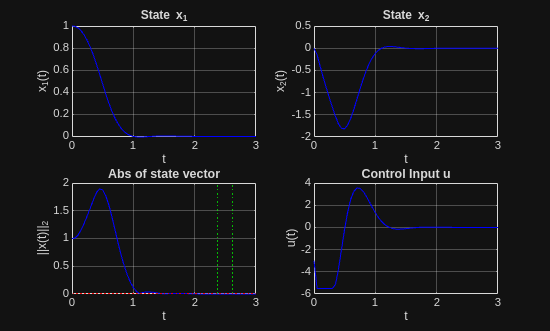


figure;
subplot(221); plot(out.x.Time,out.x.Data(:,1),'b'), grid on,
    xlabel('t'), ylabel('x_1(t)'), title('State x_1');
subplot(222); plot(out.x.Time,out.x.Data(:,2),'b'), grid on,
    xlabel('t'), ylabel('x_2(t)'), title('State x_2');
subplot(223); plot(out.x.Time,sqrt(out.x.Data(:,1) .^2+out.x.Data(:,2) .^2),'b'), grid on,
    xlabel('t'), ylabel('||x(t)||_2'), title('Abs of state vector')
    xline(2.5-5/100*2.5,':g'),xline(2.5+5/100*2.5,':g')
    yline(-1e-4,':r'), yline(1e-4,':r');
subplot(224); plot(out.u.Time,out.u.data,'b'), grid on,
    xlabel('t'),ylabel('u(t)'), title('Control Input u');